# Pregunta 2 Hodrick–Prescott filtering

clear;
clc;
DataBC = readtable('Data_BC.xlsx');

DataBC(1,:) = [];

## a) Separacion de la data

Separamos la data en el precio del cobre (variable cu medida en dolares por libra de cada mes) , el del petroleio (variable p medida en dolares por barril de cada mes) y el valor de la inflación (variable inf medida en cambio porcentual mesual)

cu = table2array(DataBC(:, 2));
p = table2array(DataBC(:, 3));
inf = table2array(DataBC(:, 4));

## b) Funcion que descompone

La variable "c" es el ciclo y "s" la tendencia. La función está creada al final del script

[c, s] = HP(cu, 14400);

## c) Gráfico de la descomposición HP del precio del cobre

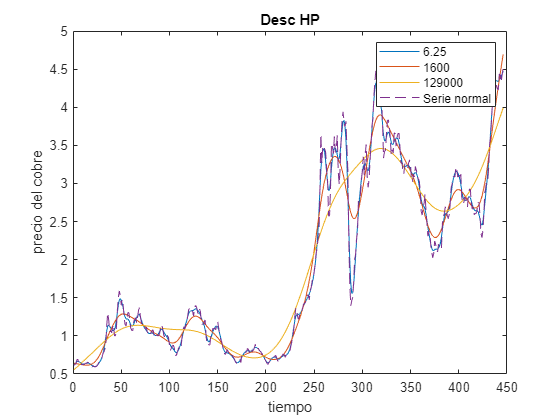

[c_l, s_l] = HP(cu, 6.25);
[c_M, s_M] = HP(cu, 1600);
[c_H, s_H] = HP(cu, 129000);
x = 1:length(s);
plot(x, s_l, x, s_M, x, s_H, x, s + c, "--")
title("Desc HP")
ylabel("precio del cobre")
xlabel("tiempo")
legend("6.25","1600","129000","Serie normal")

## d) Regresion lineal

Los vectores con data del periodo anterior no son más que un shift hacia atras de los datos originales.

cu_s = circshift(cu, 1);
cu_s(1) = 0;
p_s = circshift(p, 1);
p_s(1) = 0;
inf_s = circshift(inf, 1);
inf_s(1) = 0;


## Creamos las X y las variables explicadas o dependientes (Y)

unos = ones(size(inf, 1), 1);
M1 = [unos inf_s cu cu_s];
M2 = [unos inf_s p p_s];
M1(1, :) = [];
M2(1, :) = [];
% ajustamos la y
inf_y = inf;
inf_y(1) = [];

betas1 = (M1'*M1)\M1'*inf_y;
betas2 = (M2'*M2)\M2'*inf_y;

## functions

function [c, s] = HP(y, lambda)
n = length(y);
A = MatrixA(n, lambda);
c = (eye(n) - inv(A))* y;
s = A\y;
end

function A = MatrixA(m, lambda)
K = MatrixK(m);
I = eye(m);
A = I + lambda* (K'* K);
end

function K = MatrixK(m)
K = zeros(m - 2, m);
for i = 1:(m - 2)
    K(i, i) = 1;
    K(i, i + 1) = -2;  
    K(i, i + 2) = 1;
end
end